syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.42;0.473;4.01];
u31=[-0.856;-0.117;0.504];
r2=[-3.42;-0.473;-4.21];
u32=[0.856;0.117;0.504];
r3=[-10.14;-8.36;3.94];
u33=[-0.856;-0.117;-0.504];
r4=[-10.14;-8.36;-12.50];
u34=[-0.856;-0.117;-0.504];
r5=[7.69;-9.29;-4.28];
u35=[0.856;0.117;-0.504];
r6=[7.69;-9.29;12.16];
u36=[0.856;0.117;-0.504];
% center and direction of spheroids

axis([1 10 1 10]);
for R3=1:0.2:10 %离心率
    R1=2;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    hold on
    scatter(R1,R3,'b')
    xlabel('R1'); ylabel('R3');
end

ans =    10.4500    1.0000    1.0019


ans =    10.2000    1.2000    1.0042


ans =     9.9500    1.4000    1.0060


ans =     9.7000    1.6000    1.0075


ans =     9.4500    1.8000    1.0085


ans =     9.2500    2.0000    1.0005


ans =     9.0000    2.2000    1.0007


ans =     8.7500    2.4000    1.0005


ans =     8.4500    2.6000    1.0085


ans =     8.2000    2.8000    1.0077


ans =     7.9500    3.0000    1.0069


ans =     7.7000    3.2000    1.0060


ans =     7.4500    3.4000    1.0055


ans =     7.2000    3.6000    1.0055


ans =     6.9500    3.8000    1.0064


ans =     6.7000    4.0000    1.0084


ans =     6.5000    4.2000    1.0030


ans =     6.2500    4.4000    1.0082


ans =     6.0500    4.6000    1.0063


ans =     5.8500    4.8000    1.0063


ans =     5.6500    5.0000    1.0083


ans =     5.5000    5.2000    1.0024


ans =     5.3000    5.4000    1.0083


ans =     5.1500    5.6000    1.0055


ans =     5.0000    5.8000    1.0041


ans =     4.8500    6.0000    1.0038


ans =     4.7000    6.2000    1.0043


ans =     4.5500    6.4000    1.0056


ans =     4.4000    6.6000    1.0075


ans =     4.2500    6.8000    1.0097


ans =     4.1500    7.0000    1.0008


ans =     4.0000    7.2000    1.0032


ans =     3.8500    7.4000    1.0055


ans =     3.7000    7.6000    1.0076


ans =     3.5500    7.8000    1.0094


ans =     3.4000    8.0000    1.0108


ans =     3.3000    8.2000    1.0009


ans =     3.1500    8.4000    1.0016


ans =     3.0000    8.6000    1.0017


ans =     2.8500    8.8000    1.0014


ans =     2.7000    9.0000    1.0005


ans =     2.5000    9.2000    1.0094


ans =     2.3500    9.4000    1.0075


ans =     2.2000    9.6000    1.0050


ans =     2.0500    9.8000    1.0021


ans =     1.8500   10.0000    1.0085




for R3=1.4:0.2:10 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
  
    scatter(R1,R3,'r')
    xlabel('R1'); ylabel('R3');
end

ans =    18.1000    1.4000    1.0002


ans =    10.9000    1.6000    1.0019


ans =     9.2000    1.8000    1.0052


ans =     8.4000    2.0000    1.0058


ans = 1×3
    7.9500    2.2000    1.0027


ans = 1×3
    7.6500    2.4000    1.0009


ans = 1×3
    7.4000    2.6000    1.0074


ans = 1×3
    7.2500    2.8000    1.0056


ans = 1×3
    7.1500    3.0000    1.0009


ans = 1×3
    7.0500    3.2000    1.0020


ans = 1×3
    6.9500    3.4000    1.0080


ans = 1×3
    6.9000    3.6000    1.0051


ans = 1×3
    6.8500    3.8000    1.0050


ans = 1×3
    6.8000    4.0000    1.0070


ans = 1×3
    6.7500    4.2000    1.0108


ans = 1×3
    6.7500    4.4000    1.0025


ans = 1×3
    6.7000    4.6000    1.0090


ans = 1×3
    6.7000    4.8000    1.0027


ans = 1×3
    6.6500    5.0000    1.0111


ans = 1×3
    6.6500    5.2000    1.0061


ans = 1×3
    6.6500    5.4000    1.0017


ans = 1×3
    6.6000    5.6000    1.0121


ans = 1×3
    6.6000    5.8000    1.0085


ans = 1×3
    6.6000    6.0000    1.0053


ans = 1×3
    6.6000    6.2000    1.0024


ans = 1×3
    6.5500    6.4000    1.0145


ans = 1×3
    6.5500    6.6000    1.0121


ans = 1×3
    6.5500    6.8000    1.0099


ans = 1×3
    6.5500    7.0000    1.0079


ans = 1×3
    6.5500    7.2000    1.0061


ans = 1×3
    6.5500    7.4000    1.0044


ans = 1×3
    6.5500    7.6000    1.0028


ans = 1×3
    6.5500    7.8000    1.0014


ans = 1×3
    6.5500    8.0000    1.0000


ans = 1×3
    6.5000    8.2000    1.0138


ans = 1×3
    6.5000    8.4000    1.0127


ans = 1×3
    6.5000    8.6000    1.0116


ans = 1×3
    6.5000    8.8000    1.0106


ans = 1×3
    6.5000    9.0000    1.0097


ans = 1×3
    6.5000    9.2000    1.0088


ans = 1×3
    6.5000    9.4000    1.0080


ans = 1×3
    6.5000    9.6000    1.0072


ans = 1×3
    6.5000    9.8000    1.0065


ans = 1×3
    6.5000   10.0000    1.0058


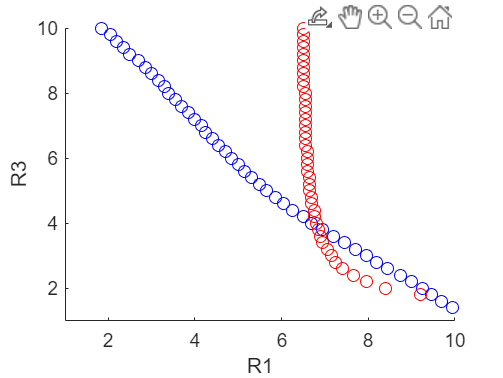




hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

